close all;
format long 

% Read file
filename = "2016_pitches_excel2.csv";
tbl = readtable(filename,'TextType','String');

% Convert Pitch Types to categorical
labelName = "Pitch_Type";
tbl = convertvars(tbl,labelName,'categorical');

% Use random nonstratified partition to split the data
% Stratified partition takes subpopulations, nonstratified takes the entire
% population
rng('default')
n = height(tbl(:,1));
hpartition = cvpartition(n,'Holdout',0.3); % Nonstratified partition
idxTrain = training(hpartition);
tblTrain = tbl(idxTrain,:)

tblTrain = 242017×10 table
    Score_Diff    Balls    Strikes    Outs    Pitch_Number    Runner_First    Runner_Second    Runner_Third    Half_Inning        Pitch_Type    
    __________    _____    _______    ____    ____________    ____________    _____________    ____________    ___________    __________________

        0           0         0        0           1               0                0               0               1         Two_Seam_Fastball 
        0           1         2        0           4               0                0               0               1         Two_Seam_Fastball 
        0           2         2        0           5

idxNew = test(hpartition);
tblNew = tbl(idxNew,:)

tblNew = 103721×10 table
    Score_Diff    Balls    Strikes    Outs    Pitch_Number    Runner_First    Runner_Second    Runner_Third    Half_Inning        Pitch_Type    
    __________    _____    _______    ____    ____________    ____________    _____________    ____________    ___________    __________________

         0          0         1        0           2               0                0               0               1         Curveball         
         0          0         2        0           3               0                0               0               1         Two_Seam_Fastball 
         0          0         1        1           2  

Learner types to explore: ensemble, nb, net, tree
Total iterations (MaxObjectiveEvaluations): 120
Total time (MaxTime): 20

|=============================================================================================================================================|
| Iter | Eval   | Validation | Time for training | Observed min    | Estimated min   | Learner      | Hyperparameter:                 Value   |
|      | result | loss       | & validation (sec)| validation loss | validation loss |              |                                         |
|=============================================================================================================================================|
|    1 | Best   |    0.61607 |            8.1975 |         0.61607 |         0.61607 |         tree | MinLeafSize:                         21 |
|    2 | Accept |    0.61607 |            7.9216 |         0.61607 |         0.61607 |         tree | MinLeafSize:                         21 |
|    3 | Bes

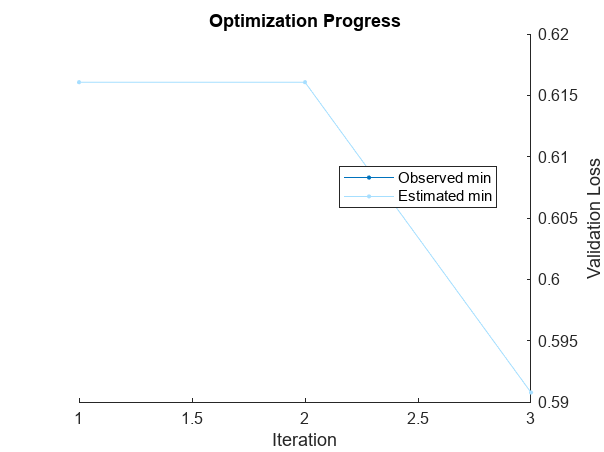


__________________________________________________________
Optimization completed.
Total iterations: 3
Total elapsed time: 47.1983 seconds
Total time for training and validation: 44.0594 seconds

Best observed learner is a net model with:
	Learner:                   net
	Activations:           sigmoid
	Standardize:             false
	Lambda:               0.043247
	LayerSizes:        [6  25  14]
Observed validation loss: 0.59078
Time for training and validation: 27.9404 seconds

Best estimated learner (returned model) is a net model with:
	Learner:                   net
	Activations:           sigmoid
	Standardize:             false
	Lambda:               0.043247
	LayerSizes:        [6  25  14]
Estimated validation loss: 0.59078
Estimated time for training and validation: 27.9404 seconds

Documentation for fitcauto display


Mdl =   CompactClassificationNeuralNetwork
               LayerSizes: [6 25 14]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'


  Properties, Methods



% Train Support Vector Machine (SVM) model
Mdl = fitcauto(tblTrain,"Pitch_Type","HyperparameterOptimizationOptions",struct("ShowPlots",true,"MaxTime",20))


[x,~,iteration] = bestPoint(Results,"Criterion","min-visited-mean");
cvError = Results.ObjectiveTrace(iteration);+*/87cvAccuracy = 1 - cvError

cvAccuracy =    0.383931707276755


Error using crossval
The first input must be 'mse' or 'mcr' or a function handle.